clear;clc
load ('F_otoc_[-0.125,-0.025,0.15].mat')
load ('STD_F_[-0.125,-0.025,0.15].mat')
F_otoc1=F;
STD_F_otoc1=STD_F;

load ('F_otoc_[-0.1,0.1,0].mat')
load ('STD_F_[-0.1,0.1,0].mat')
F_otoc2=F;
STD_F_otoc2=STD_F;

load STD_Cz_[-0.125,-0.025,0.15]
load Cz_[-0.125,-0.025,0.15]
load STD_Cz_[-0.1,0.1,0]
load Cz_[-0.1,0.1,0]

S1=S_mono;
STD_S1=STD_S_mono;
S2=S_oscillate;
STD_S2=STD_S_oscillate;

load('J1.mat') %The calibration results of J
load('J1_uncert.mat')
J1_seq=reshape(J1_seq,[70,1]);
J_bar=mean(J1_seq)*1e-3; %The average value of J, in kHz.


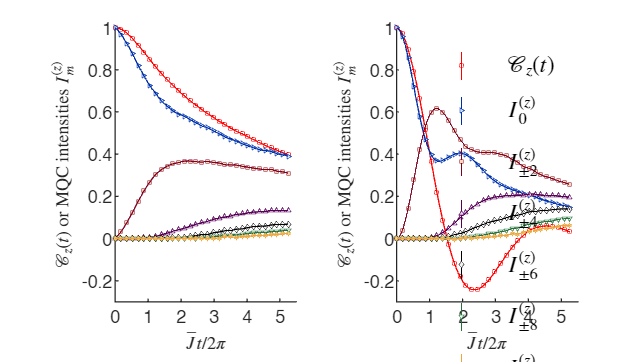

markerfacecolor={"#C9E1FF",'#FFD5B4','#EAD7FF','#F2F2F2','#DFFFE5','#E0DF94'};
markeredgecolor={'#002FA7','#800020','#56004F','k','#2A6E3F','#EFA442'};

marker={'>','s','^','d','v','h'};
markersize=[1.8,1.8,1.8,1.8,1.8,1.8];

figure()
subplot(1,2,1)
tau=5*1e-6;
quench_time_seq=24*tau*(0:30)*1e3; %in ms

x=quench_time_seq*J_bar;
xx=linspace(x(1),x(end),100);
hold off
errorbar(x,S1(1:31),1.96*STD_S1(1:31),'o','MarkerSize',markersize(1),'Color','r','CapSize',0,'linewidth',0.25);
hold on
yy=spline(x,S1(1:31),xx);
plot(xx,yy,'r','linewidth',0.25)

L=32;
Y1=real(fft(F_otoc1,L,2))/L;
mqc1=[Y1(:,1),2*Y1(:,2:L/2)];
std_zeroorder1=(mean(STD_F_otoc1,2))/L^0.5;
std_otherorder1=2*(mean(STD_F_otoc1,2))/(2*L)^0.5;

ii=1;
error_bar=1.96*std_zeroorder1;
errorbar(x,mqc1(:,1),error_bar,marker{ii},'MarkerSize',markersize(ii),'linewidth',0.25,'markerfacecolor',markerfacecolor{ii},'markeredgecolor',markeredgecolor{ii},'color',markeredgecolor{ii},'capsize',0);

yy=spline(x,mqc1(:,1),xx);
plot(xx,yy,'color',markeredgecolor{ii},'linewidth',0.25)

for i=2:6
    ii=ii+1;
    error_bar=1.96*std_otherorder1;
    y=mqc1(:,2*i-1);
    errorbar(x,y,error_bar,marker{ii},'MarkerSize',markersize(ii),'linewidth',0.25,'markerfacecolor',markerfacecolor{ii},'markeredgecolor',markeredgecolor{ii},'color',markeredgecolor{ii},'capsize',0);

    yy=spline(x,y,xx);
    plot(xx,yy,'color',markeredgecolor{ii},'linewidth',0.25)
end

xlabel('$\bar{J}t/2\pi$','Interpreter','latex')
ylabel('$\mathcal{C}_z(t)$ or MQC intensities $I_m^{(z)}$','Interpreter',"latex")
ylim([-0.3 1])
yticks([-0.4:0.2:1])
% yticklabels({'-0.5', '0', '0.5', '1'})
xlim([0,5.5])
xticks([0:1:5])
set(gca,'box','off')

subplot(1,2,2)
tau=5*1e-6;
quench_time_seq=24*tau*(0:30)*1e3; %in ms
hold off
x=quench_time_seq*J_bar;
errorbar(x,S2(1:31),1.96*STD_S2(1:31),'o','MarkerSize',markersize(1),'Color','r','CapSize',0,'linewidth',0.25);
hold on
yy=spline(x,S2(1:31),xx);
plot(xx,yy,'color','r','linewidth',0.25)

L=32;
Y2=real(fft(F_otoc2,L,2))/L;
mqc2=[Y2(:,1),2*Y2(:,2:L/2)];
std_zeroorder2=(mean(STD_F_otoc2,2))/L^0.5;
std_otherorder2=2*(mean(STD_F_otoc2,2))/(2*L)^0.5;

ii=1;
error_bar=1.96*std_zeroorder2;
errorbar(x(1:31),mqc2(:,1),error_bar,marker{ii},'MarkerSize',markersize(ii),'linewidth',0.25,'markerfacecolor',markerfacecolor{ii},'markeredgecolor',markeredgecolor{ii},'color',markeredgecolor{ii},'capsize',0);

yy=spline(x,mqc2(:,1),xx);
plot(xx,yy,'color',markeredgecolor{ii},'linewidth',0.25)

for i=2:6
    ii=ii+1;
    error_bar=1.96*std_otherorder2;
    y=mqc2(:,2*i-1);
    errorbar(x(1:31),y,error_bar,marker{ii},'MarkerSize',markersize(ii),'linewidth',0.25,'markerfacecolor',markerfacecolor{ii},'markeredgecolor',markeredgecolor{ii},'color',markeredgecolor{ii},'capsize',0);

    xx=linspace(x(1),x(end),10000);
    yy=spline(x,y,xx);
    plot(xx,yy,'color',markeredgecolor{ii},'linewidth',0.25)
end

set(gca,'box','off')
xlabel('$\bar{J}t/2\pi$','Interpreter','latex')
ylabel('$\mathcal{C}_z(t)$ or MQC intensities $I_m^{(z)}$','Interpreter',"latex")
% ylabel('$\mathcal{C}_z(t)$ or MQC intensities $I_m(t)$','Interpreter',"latex")
ylim([-0.3 1])
% yticklabels({'-0.5', '0', '0.5', '1'})
xlim([0,5.5])
xticks([0:1:5])
fontsize(gcf,7,'points')
% fontname(gcf,"Times New Roman")
fontname(gcf,"Helvetica")

legend('$\mathcal{C}_z(t)$','','$I_{0}^{(z)}$','','$I_{\pm2}^{(z)}$','','$I_{\pm4}^{(z)}$','','$I_{\pm6}^{(z)}$','','$I_{\pm8}^{(z)}$','','$I_{\pm10}^{(z)}$','interpreter','latex','box','off','FontSize',9)
set(gcf,'unit','centimeters','position',[10,10,9,5.1]);

Determine $t_{\textrm{dip}} ,\;t_{\textrm{peak}}$

    xx=linspace(x(1),x(end),100000);
    yy=spline(x,mqc2(:,3),xx);
    [~,index]=max(yy);
    t_peak_2MQC=xx(index)

t_peak_2MQC = 1.2207



    xx=linspace(x(1),x(12),100000);
    yy=spline(x,mqc2(:,1),xx);
    [~,index]=min(yy);
    t_dip_0MQC=xx(index)

t_dip_0MQC = 1.2919

    xx=linspace(x(1),x(end),100000);
    yy=spline(x,S2(1:31),xx);
    [~,index]=min(yy);
    t_dip_Cz=xx(index)

t_dip_Cz = 2.3674

filename = 'Figure_4.xlsx';
writematrix(roundn(x',-5),filename,'Sheet','Figure 4a','Range','A4')
writematrix(roundn(S1(1:31)',-5),filename,'Sheet','Figure 4a','Range','B4')
writematrix(roundn(mqc1(:,1:2:11),-5),filename,'Sheet','Figure 4a','Range','C4')
writematrix(roundn(1.96*STD_S1(1:31)',-5),filename,'Sheet','Figure 4a','Range','J4')
writematrix(roundn(1.96*std_zeroorder1,-5),filename,'Sheet','Figure 4a','Range','K4')
writematrix(roundn(1.96*std_otherorder1,-5),filename,'Sheet','Figure 4a','Range','L4')


writematrix(roundn(x',-5),filename,'Sheet','Figure 4b','Range','A4')
writematrix(roundn(S2(1:31)',-5),filename,'Sheet','Figure 4b','Range','B4')
writematrix(roundn(mqc2(:,1:2:11),-5),filename,'Sheet','Figure 4b','Range','C4')
writematrix(roundn(1.96*STD_S2(1:31)',-5),filename,'Sheet','Figure 4b','Range','J4')
writematrix(roundn(1.96*std_zeroorder2,-5),filename,'Sheet','Figure 4b','Range','K4')
writematrix(roundn(1.96*std_otherorder2,-5),filename,'Sheet','Figure 4b','Range','L4')